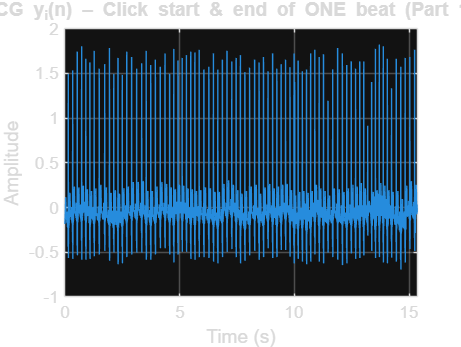

clear; close all; clc;

%% Load ideal signal
load('/MATLAB Drive/BSP_assignment2/Weiner filtering/idealECG.mat');  % should load yi (ideal ECG), optionally Fs
if ~exist('Fs','var') || isempty(Fs)
    Fs = 500; % Hz
end
yi = idealECG(:);                 % ensure column
N  = length(yi);
t  = (0:N-1).' / Fs;

%% Build noisy input x(n) = yi + eta
% White Gaussian noise such that SNR(yi vs eta_wg) = 10 dB
Py        = mean(yi.^2);
SNR_dB    = 10;
Pwgn_need = Py / (10^(SNR_dB/10));
eta_wg    = sqrt(Pwgn_need) * randn(N,1);

% 50 Hz sinusoid of amplitude 0.2
eta50     = 0.2 * sin(2*pi*50*(0:N-1)'/Fs);

eta       = eta_wg + eta50;
x         = yi + eta;

%% Visualize raw signals and pick segments
figure('Name','Pick segments','Color','w'); 
plot(t, yi); grid on; xlabel('Time (s)'); ylabel('Amplitude');
title('ideal ECG y_i(n) – Click start & end of ONE beat (Part 1 desired)');


% Pick one beat in yi
disp('Select START and END of a single beat in y_i(n) …');

Select START and END of a single beat in y_i(n) …


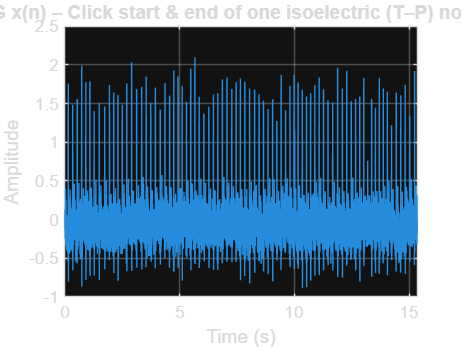

tStart = 4.496;   % start at 2s
tEnd   = 4.65;   % end at 3s
idxBeat = round(tStart*Fs) : round(tEnd*Fs);
K = 12;  % number of knots for the linear model (tweak if needed)
idx_knots = round(linspace(idxBeat(1), idxBeat(end), K));
t_knots   = t(idx_knots);
y_knots   = yi(idx_knots);

% Build piecewise-linear template at beat positions, then extend zeros elsewhere
y_linear_model = zeros(N,1);
% linear interpolation on the beat support
tBeat = t(idxBeat);
y_linear_model(idxBeat) = interp1(t_knots, y_knots, tBeat, 'linear');
y_desired_part2 = y_linear_model(idxBeat);


if idxBeat(1) == idxBeat(end)
    warning('You selected a single point — please select a wider range.');
end

figure('Name','Pick segments','Color','w');
plot(t, x); grid on; xlabel('Time (s)'); ylabel('Amplitude');
title('noisy ECG x(n) – Click start & end of one isoelectric (T–P) noise segment');


% Pick one isoelectric noise segment in x
disp('Select START and END of an isoelectric (T–P) segment in x(n) …');

Select START and END of an isoelectric (T–P) segment in x(n) …


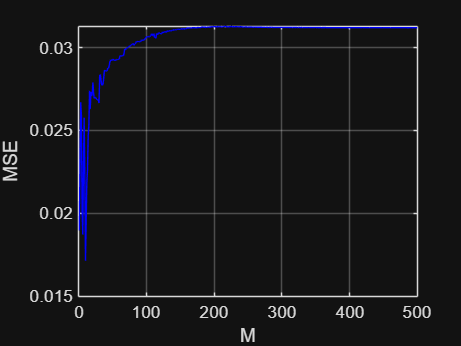

tStart = 4.814;   % start at 2s
tEnd   = 4.86;   % end at 3s
idxNoise = round(tStart*Fs) : round(tEnd*Fs);
n_seg    = x(idxNoise);      % noise-dominant segment (assumes minimal underlying ECG)
tNoise   = t(idxNoise);



% === helper for biased autocorr and Toeplitz R ===
autocorr_biased = @(s, M) xcorr(s, M-1, 'biased');    % lags -(M-1):+(M-1)
nonneg = @(r, M) r(M:end);                            % extract lags 0..M-1
buildR = @(s, M) toeplitz(nonneg(autocorr_biased(s,M), M));

% search M:
Ms = 1:500;
mse_vals = zeros(size(Ms));
Wset = cell(size(Ms));

for k=1:length(Ms)
    M = Ms(k);
    
    Ryy = buildR(y_desired_part2, M);
    Rnn = buildR(n_seg, M);
    ryy = nonneg(autocorr_biased(y_desired_part2,M), M);
    w = (Ryy + Rnn) \ ryy; % optimum weights for each order(M)
    Wset{k} = w;
    yhat = filter(w, 1, x);
    e = yi(idxBeat) - yhat(idxBeat);
    mse_vals(k) = mean(e.^2);
end

figure;
plot(Ms, mse_vals, 'b');
grid on; xlabel('M'); ylabel('MSE');

%title('Selected Noise Segment from Noisy ECG');

[~,ibest] = min(mse_vals);
Mbest = Ms(ibest); w_best = Wset{ibest};
fprintf('Part 1 best M = %d\n', Mbest);

Part 1 best M = 10


fprintf('Optimum weight vector (w_best):\n');

Optimum weight vector (w_best):


disp(w_best);

    0.6545
    0.1803
   -0.0519
   -0.1372
    0.1177
    0.1264
    0.0725
    0.0250
   -0.0348
   -0.1559



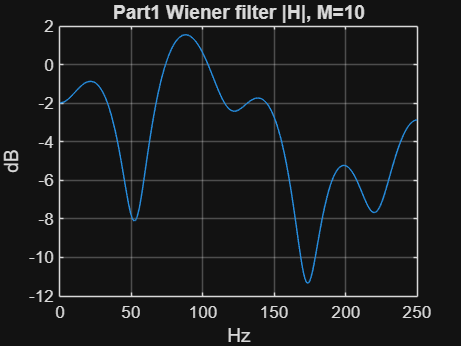


[H, f] = freqz(w_best, 1, 2048, Fs);   % 1024-point FFT, normalized to Fs
% Plots (magnitude response and spectra)
figure; plot(f,20*log10(abs(H))); grid on; xlabel('Hz'); ylabel('dB');
title(sprintf('Part1 Wiener filter |H|, M=%d', Mbest));

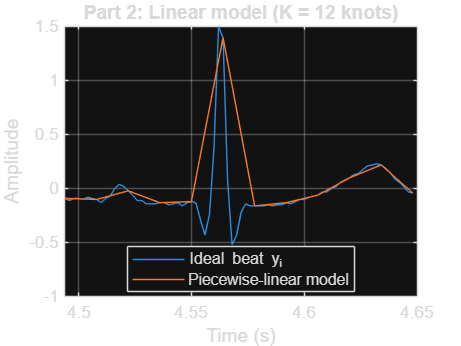


% Get filtered output, response, and spectra
yhat_best = filter(w_best, 1, x);

Nfft = 4096;
f = (0:Nfft-1)'/Nfft*Fs;
YI = fft(yi, Nfft); ETA = fft(x-yi, Nfft); Xf = fft(x,Nfft); YH = fft(yhat_best,Nfft);

%% Plot Part 2 figures
figure('Name','Part 2 – Linear Model vs Ideal (Beat Window)','Color','w');
plot(tBeat, yi(idxBeat)); hold on; grid on;
plot(tBeat, y_linear_model(idxBeat));
xlabel('Time (s)'); ylabel('Amplitude');
legend('Ideal beat y_i','Piecewise-linear model','Location','best');
title(sprintf('Part 2: Linear model (K = %d knots)', K));

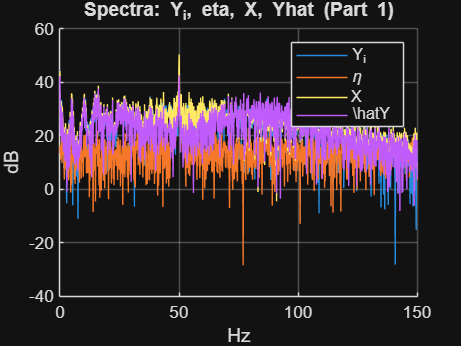


figure; hold on;
plot(f,20*log10(abs(YI))); plot(f,20*log10(abs(ETA)));
plot(f,20*log10(abs(Xf))); plot(f,20*log10(abs(YH)));
xlim([0 150]); legend('Y_i','\eta','X','\hat{Y}'); xlabel('Hz'); ylabel('dB'); grid on;
title('Spectra: Y_i, eta, X, Yhat (Part 1)'); hold off;

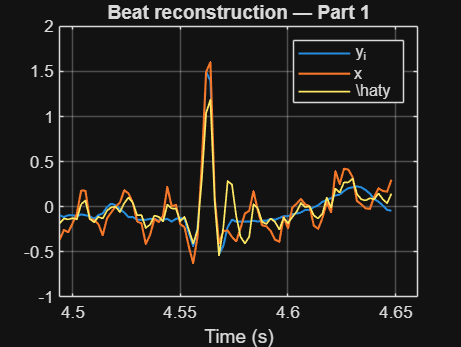


figure; plot(t(idxBeat), yi(idxBeat), 'LineWidth',1.2); hold on;
plot(t(idxBeat), x(idxBeat), 'LineWidth',1.2); hold on;
plot(t(idxBeat), yhat_best(idxBeat), 'LineWidth',1.0); grid on;
xlabel('Time (s)'); legend('y_i','x','\hat{y}'); title('Beat reconstruction — Part 1');


signal_power = Py

signal_power = 0.0719

noise_power  = mean((yi - yhat_best).^2);

SNR_filtered = 10*log10(signal_power / noise_power);

fprintf('Filtered Signal SNR = %.2f dB\n', SNR_filtered);

Filtered Signal SNR = 6.02 dB
